# **Assignment 2: Fourier Analysis**

# Jiaying Li (jli3269) and Nicolette V Cash (ncash6)

## G**eneral Instructions:**

- Make sure you use the exact function declarations given in the question descriptions. **Changes of any kind will be penalized.**

- Save every function in a separate .m file with the correct function name (e.g. functionName.m)

- Plots and discussion should be included in this Live Script (.mlx) file itself

- Plots should be properly and extensively labeled.

- Core MATLAB functions are allowed. Functions from toolboxes (such as Signal Processing Toolbox) are **not allowed** unless explicitly specified otherwise.

- Submit the MATLAB code as a link to a private github repository share with me and upload the .pdf report to canvas

- Clarification edits will be shown in **bold**.

- **STRONGLY RECOMMENDED: **Clear all variables and run this script in its entirety before submission. Make sure everything runs okay **in one go** from top to bottom.

The purpose of this assignment is to cover some of the concepts associated with Fourier transforms and spectrograms

% INITIALIZATION CODE. DO NOT CHANGE.
clearvars;
restoredefaultpath;

% take care of path
assignmentFolder = fileparts(matlab.desktop.editor.getActiveFilename); 
addpath(genpath(assignmentFolder));

topFolder = fileparts(fileparts(assignmentFolder)); 
addpath(topFolder);
addpath(genpath(fullfile(topFolder, "instructor", "qgrader")));

utilFolder = fullfile(fileparts(fileparts(topFolder)), "autograder"); 
addpath(genpath(utilFolder));


## Question 0: ** Setting up the MATLAB script [5]**

Create your copy of this MATLAB Live Script (.mlx) titled `assignment2.mlx`.

This script should call the functions below in the specified order, read the files, and generate all the required plots / figures (with proper axes and labels wherever required). This script will be executed for grading.  

Set the variable `studentId` to your GT username (e.g. `gburdell3, alerch3, kwatchar3`). **DO NOT USE YOUR EMAIL ALIAS.**

% CHANGE THIS
studentId = 'group02'; 

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% AUTOGRADER -- DO NOT EDIT OR DELETE! %%%%%%%%
score = 100; % SCORE OUT OF 100
autograde('q0', struct('score', score), studentId);

q0:	 5.00 / 5.00


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Question 1: **Generating sinusoids in MATLAB [15]**

### Q1(a) [10]

Write a function 

`[t, x] = generateSinusoidal(amplitude, sample_rate_hz, frequency_hz, length_sec, phase_radian)` 

generating a sinusoidal according to the parameters. 

**Use an appropriate trigonometric function so that when **`phase_radian`** is zero, **`x(1)`** is zero.**

The outputs `x` and `t` are the generated signal and the corresponding time **in seconds**, respectively. Both outputs must be column vectors of the same length (`N` by `1`).

**Quick check:** `t(n+1) - t(n)` should be equal to `1/sample_rate_hz` up to machine precision, for all `n`. 

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% AUTOGRADER -- DO NOT EDIT OR DELETE! %%%%%%%%
autograde('q1a', [], studentId);

fs check ok.
val check ok.

q1a:	 10.00 / 10.00





%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

### Q1(b) [2.5]

Add a function call to your script to generate a sine wave with the following parameters: 

- amplitude = 1.0, 

- sample_rate_hz = 48 kHz

- frequency_hz = 375 Hz, 

- length_sec = $\frac{256}{375}$ s, 

- phase_radian = $\frac{\pi }{2}$ rad.

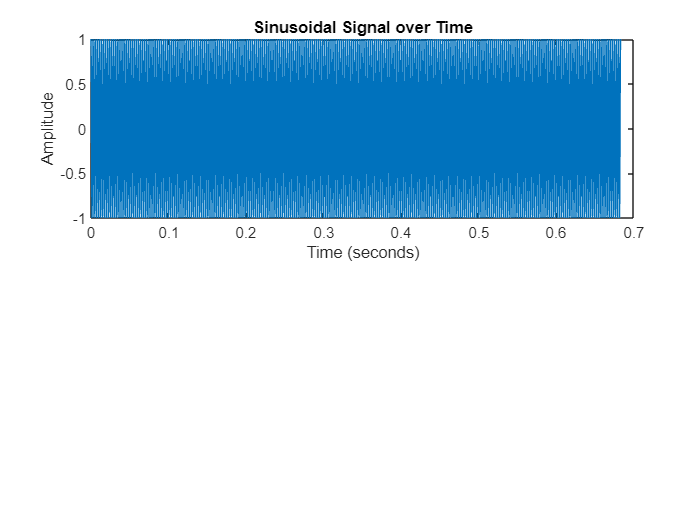

%%%% YOUR CODE HERE %%%%

amplitude = 1.0;
sample_rate_hz = 48000; % In Hertz
frequency_hz = 375; % In Hertz
length_sec = 256/375; % Decimal Seconds
phase_radian = pi/2; % In Radians

[t_sin,x_sin] = generateSinusoidal(amplitude, sample_rate_hz, frequency_hz, length_sec, phase_radian); % Sinusoidal Wave Function Call

figure("name", "Plot for Sinusoidal Wave"); % The generated sinusoidal Signal and corresponding time in seconds
subplot(2,1,1);plot(t_sin, x_sin);title("Sinusoidal Signal over Time");
xlabel("Time (seconds)");ylabel("Amplitude");


%%% END OF YOUR CODE %%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% AUTOGRADER -- DO NOT EDIT OR DELETE! %%%%%%%%
autograde('q1b', struct('t', t_sin, 'x', x_sin), studentId);

t
  - Correct shape.
  - Correct values.
x
  - Correct shape.
  - Correct values.
q1b:	 2.50 / 2.50





%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

### Q1(c) [2.5]

Plot the first 5 ms of the sinusoid generated above (label the axes correctly, time axis must be in seconds)

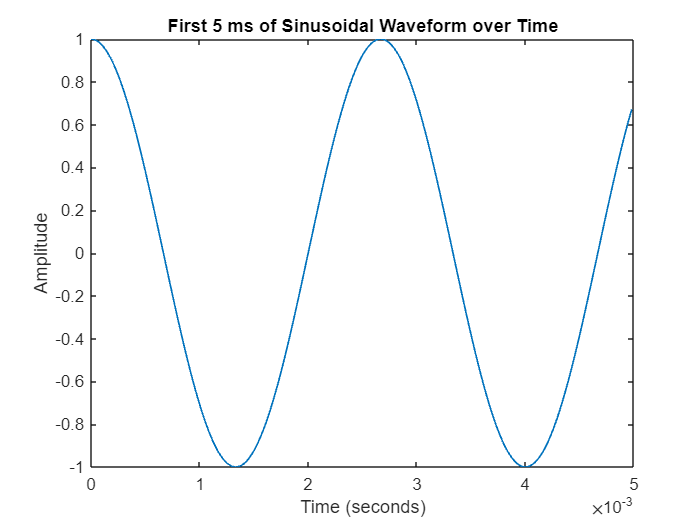

% ADD YOUR CODE
figure;
range = 0.005*sample_rate_hz; % Calculated End Sample of 5ms Sine Wave
plot(t_sin(1:range), x_sin(1:range),'Linewidth',1);xlabel("Time (seconds)");ylabel("Amplitude") % Generated Line Information
title("First 5 ms of Sinusoidal Waveform over Time")


% END OF YOUR CODE

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% AUTOGRADER -- DO NOT EDIT OR DELETE! %%%%%%%%
autograde('q1c', [], studentId);

q1c:	 2.50 / 2.50





%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## **Question 2: Combining Sinusoids to generate waveforms with complex spectra [20]**

### Q2(a) [15]

Write a function 

`[t,x] = generateSquare(amplitude, sample_rate_hz, frequency_hz, length_sec, phase_radian)`

that generates a zero-mean square wave approximated with 10 sinusoidals according to the parameters. 

The outputs `x` and `t` are the generated signal and the corresponding time is seconds. Both outputs must be column vectors of the same length (`N` by `1`). 

**Note:** use the `generateSinusoidal` function from Question 1(a) for this part

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% AUTOGRADER -- DO NOT EDIT OR DELETE! %%%%%%%%
autograde('q2a', [], studentId);

t
  - Correct shape.
  - Correct values.
x
  - Correct shape.
  - Correct values.

q2a:	 15.00 / 15.00





%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

### Q2(b) [2.5]

Add function calls to your main script to create a "square" wave, as defined above, with the following parameters: 

- amplitude = 1.0, 

- sample_rate_hz = 48 kHz

- frequency_hz = 375 Hz, 

- length_sec = $\frac{256}{375}$ s, 

- phase_radian = 0 rad.

% ADD YOUR CODE

amplitude = 1.0;
sample_rate_hz = 48000; % In Hertz
frequency_hz = 375; % In Hertz
length_sec = 256/375; % Decimal Seconds
phase_radian = 0; % In Radians

[t_sqr,x_sqr] = generateSquare(amplitude, sample_rate_hz, frequency_hz, length_sec, phase_radian); % Square Wave Function Call
% 
% figure("name", "Plot for Square Wave"); % The generated sinusoidal Signal and corresponding time in seconds
% subplot(2,1,1);plot(t_sin, x_sin);title("Square Signal over Time");
% xlabel("Time (seconds)");ylabel("Amplitude");
% END OF YOUR CODE

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% AUTOGRADER -- DO NOT EDIT OR DELETE! %%%%%%%%
autograde('q2b', struct('t', t_sqr, 'x', x_sqr), studentId);

q2b:	 2.50 / 2.50





%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

### Q2(c) [2.5]

Plot the first 5 ms of the generated square waves in Q2(b). Plot this on the same plot as the sine wave from Q1. (Provide a legend, label the axes correctly, time axis must be in seconds)

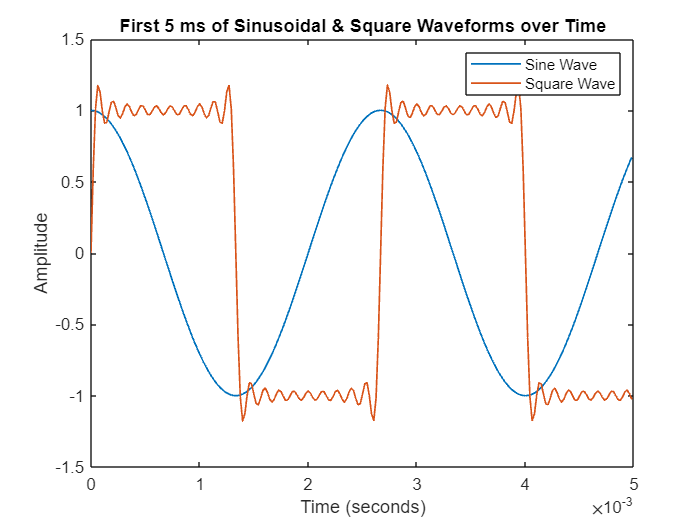

% ADD YOUR CODE
figure;
range = 0.005*sample_rate_hz; % Calculated End Sample of 5ms Sine & Square Waves
plot(t_sin(1:range), x_sin(1:range), t_sqr(1:range), x_sqr(1:range),"Linewidth",1);xlabel("Time (seconds)");ylabel("Amplitude") % Generated Line Information
title("First 5 ms of Sinusoidal & Square Waveforms over Time")
legend("Sine Wave", "Square Wave")


% END OF YOUR CODE

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% AUTOGRADER -- DO NOT EDIT OR DELETE! %%%%%%%%
autograde('q2c', [], studentId);

q2c:	 2.50 / 2.50





%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## **Question 3. Fourier Transform [30]**

### Q3(a) [15]

Write a function 

`[f, Xabs, Xphase, Xre, Xim] = computeSpectrum(x, sample_rate_hz)`

that computes the FFT of the complete input signal vector `x` and returns the magnitude spectrum `Xabs`, the phase spectrum `Xphase`, the real part `Xre`, and the imaginary part `Xim`, the frequency of the bins `f`. All outputs should be column vectors, each of length `floor(nx/2)+1` where `nx` is the length of `x`. **If your signal length is not already a power of 2**, **zero pad the signal to the next power of 2.**

All outputs must be column vectors. Return only the non-redundant part (without conjugate symmetry). 

You may use the MATLAB `fft` function in order to compute the FFT. 

Useful function: `nextpow2`

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% AUTOGRADER -- DO NOT EDIT OR DELETE! %%%%%%%%
autograde('q3a', [], studentId);

f
  - Transposition error.
  - Correct values.
Xabs
  - Correct shape.
  - Correct values.
Xphase
  - Correct shape.
  - Correct values.
Xre
  - Correct shape.
  - Correct values.
Xim
  - Correct shape.
  - Correct values.
q3a:	 14.25 / 15.00





%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

### Q3(b) [1]

Add function calls to your main script to compute the spectrum of the sinusoid and square waves generated in Questions 1(b) and 2(b)

% ADD YOUR CODE

[f_sin, Xabs_sin, Xphase_sin, Xre_sin, Xim_sin] = computeSpectrum(x_sin, sample_rate_hz); % Function Call for Fourier Transform of Sine Wave Spectrum
% 
% figure("name", "Plots for Sinusoidal Wave");
% subplot(2,2,1);plot(f_sin, Xabs_sin, "Linewidth",1);title("Sinusoidal Wave Magnitude Spectrum (Xabs)");
% xlabel("Frequency (Hz)");ylabel("Magnitude");
% subplot(2,2,2);plot(f_sin, Xphase_sin, "Linewidth",1);title("Sinusoidal Wave Phase Spectrum (Xphase)");
% xlabel("Frequency (Hz)");ylabel("Phase");
% subplot(2,2,3);plot(f_sin, Xre_sin, "Linewidth",1);title("Sinusoidal Wave Real Part (Xre)");
% xlabel("Frequency (Hz)");ylabel("Magnitude");
% subplot(2,2,4);plot(f_sin, Xim_sin, "Linewidth",1);title("Sinusoidal Wave Imaginary Part (Xim)");
% xlabel("Frequency (Hz)");ylabel("Magnitude");

[f_sqr, Xabs_sqr, Xphase_sqr, Xre_sqr, Xim_sqr] = computeSpectrum(x_sqr, sample_rate_hz); % Function Call for Fourier Transform of Square Wave Spectrum
% 
% figure("name", "Plots for Square Wave");
% subplot(2,2,1);plot(f_sqr, Xabs_sqr, "Linewidth",1);title("Sqare Wave Magnitude Spectrum (Xabs)");
% xlabel("Frequency (Hz)");ylabel("Magnitude");
% subplot(2,2,2);plot(f_sqr, Xphase_sqr, "Linewidth",1);title("Square Wave Phase Spectrum (Xphase)");
% xlabel("Frequency (Hz)");ylabel("Phase");
% subplot(2,2,3);plot(f_sqr, Xre_sqr, "Linewidth",1);title("Square Wave Real Part (Xre)");
% xlabel("Frequency (Hz)");ylabel("Magnitude");
% subplot(2,2,4);plot(f_sqr, Xim_sqr, "Linewidth",1);title("Squre Wave Imaginary Part (Xim)");
% xlabel("Frequency (Hz)");ylabel("Magnitude");

% END OF YOUR CODE

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% AUTOGRADER -- DO NOT EDIT OR DELETE! %%%%%%%%
autograde('q3b', struct( ...
    'f_sin', f_sin, ...
    'Xabs_sin', Xabs_sin, ...
    'Xphase_sin', Xphase_sin, ...
    'Xre_sin', Xre_sin, ...
    'Xim_sin', Xim_sin, ...
    'f_sq', f_sqr, ...
    'Xabs_sq', Xabs_sqr, ...
    'Xphase_sq', Xphase_sqr, ...
    'Xre_sq', Xre_sqr, ...
    'Xim_sq', Xim_sqr ...
    ), studentId);

f_sin
  - Transposition error.
  - Correct values.
Xabs_sin
  - Correct shape.
  - Correct values.
Xphase_sin
  - Correct shape.
  - Correct values.
Xre_sin
  - Correct shape.
  - Correct values.
Xim_sin
  - Correct shape.
  - Correct values.
f_sq
  - Transposition error.
  - Correct values.
Xabs_sq
  - Correct shape.
  - Correct values.
Xphase_sq
  - Correct shape.
  - Correct values.
Xre_sq
  - Correct shape.
  - Correct values.
Xim_sq
  - Correct shape.
  - Correct values.
q3b:	 0.95 / 1.00





%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

### Q3(c) [8]

For **each** of the sine and square signals, plot a figure with two subplots, one subplot for the magnitude spectrum and another for the phase spectrum. Label the titles and axes appropriately. The frequency axis must be in Hz. 

Phases at frequencies with very small magnitude contributions are generally noisy and do not provide any useful information. Using what you know about the theoretical phase of each spectrum, consider carefully how to best visualize the phase spectra to convey the information about the phase information at "important" frequencies. 

Explain briefly your choice of visualization either as text below or by commenting directly in your code.

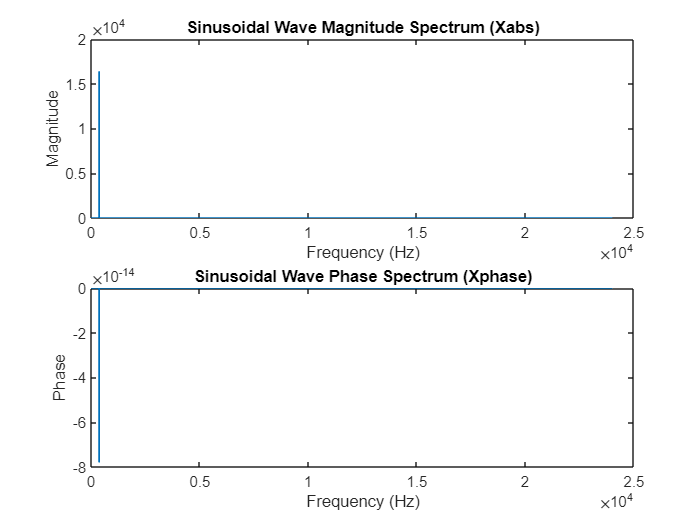

% ADD YOUR CODE

% Apply a filter to the phase spectrum. The maximum value of Xabs
% acts as the threshold.

% Sine Wave Subplot
figure("name", "Subplots for Sine Wave");
subplot(2,1,1);plot(f_sin, Xabs_sin, "Linewidth",1);title("Sinusoidal Wave Magnitude Spectrum (Xabs)"); 
xlabel("Frequency (Hz)");ylabel("Magnitude");
phasefilter_sin = Xphase_sin;
phasefilter_sin(Xabs_sin<max(Xabs_sin))=0;
subplot(2,1,2);plot(f_sin, phasefilter_sin, "Linewidth",1);title("Sinusoidal Wave Phase Spectrum (Xphase)"); 
xlabel("Frequency (Hz)");ylabel("Phase");

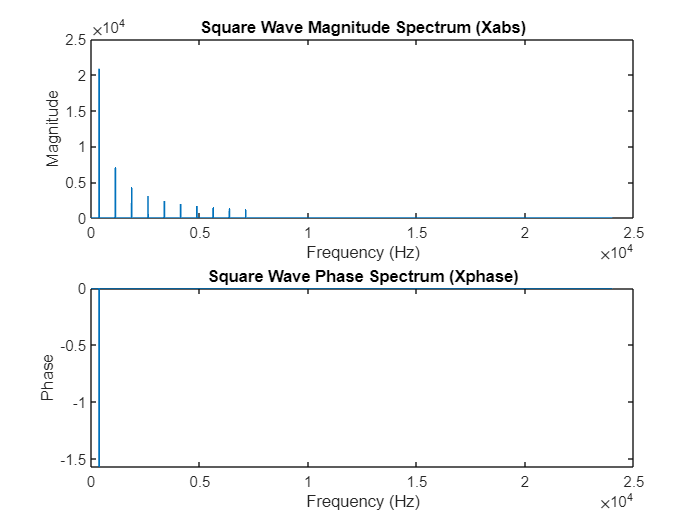


% Square Wave Subplot
figure("name", "Subplots for Square Wave");
subplot(2,1,1);plot(f_sqr, Xabs_sqr, "Linewidth",1);title("Square Wave Magnitude Spectrum (Xabs)");
xlabel("Frequency (Hz)");ylabel("Magnitude");
phasefilter_sqr = Xphase_sqr;
phasefilter_sqr(Xabs_sqr<max(Xabs_sqr))=0;
subplot(2,1,2);plot(f_sqr, phasefilter_sqr, "Linewidth",1);title("Square Wave Phase Spectrum (Xphase)");
xlabel("Frequency (Hz)");ylabel("Phase");


% END OF YOUR CODE

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% AUTOGRADER -- DO NOT EDIT OR DELETE! %%%%%%%%
autograde('q3c', struct('adjustments', {{-2, 'filtering by max power does not make sense for non-pure signal like square wave.'}}), studentId);

q3c:	 6.00 / 8.00

adjustments: 
	 -2.00 : filtering by max power does not make sense for non-pure signal like square wave.



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

### Q3(d) [2]

What is the frequency resolution (difference in frequency between the bins) of the FFT obtained above?

fRes = sample_rate_hz/length(Xabs_sin); % Difference Between Frequency Bins
formatSpec = 'The frequency resolution between the bins of the FFT above is %8.4f Hz\n';
fprintf(formatSpec,fRes)

The frequency resolution between the bins of the FFT above is   2.9295 Hz



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% AUTOGRADER -- DO NOT EDIT OR DELETE! %%%%%%%%
autograde('q3d', struct('fRes', fRes), studentId);

q3d:	 0.00 / 2.00





%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

### Q3(e) [4]

How will the frequency resolution change in this case if you zero-pad the input signal with zeros of the same length as the input signal? Explain briefly.

**Answer: When an input signal is zero-padded iwth zeros of the same length, the FFT length will be larger so the phase error will decrease. The frequency resolution will increase.**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% AUTOGRADER -- DO NOT EDIT OR DELETE! %%%%%%%%
autograde('q3e', struct('discussScore', 25), studentId);

q3e:	 1.00 / 4.00





%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

### Q3(f) [Bonus: 5]

Add a function call to your script to generate a sine wave with the following parameters: 

- amplitude = 1.0, 

- sample_rate_hz = 48 kHz

- frequency_hz = 375 Hz, 

- length_sec = 0.5 s, 

- phase_radian = $\frac{\pi}{2}$ rad.

Add a function call to your main script to compute the spectrum of the sinusoid above. Plot a figure with two subplots, one subplot for the magnitude spectrum and another for the phase spectrum. Label the titles and axes appropriately. The frequency axis must be in Hz. 

Considering that only the length of the signal has changed between this signal and the sinusoidal signal in Q1(b), explain the differences between the current plot, and that in Q3(c).

**Hint 1:** setting the y-axis to log scale might help you see the differences more clearly.

**Hint 2: **You can optionally call `computeSpectrum` on a constant signal with the same length as your new sinusoid. Does the plot match what you know about the Fourier transform of a *theoretical* constant signal? If not, why so?

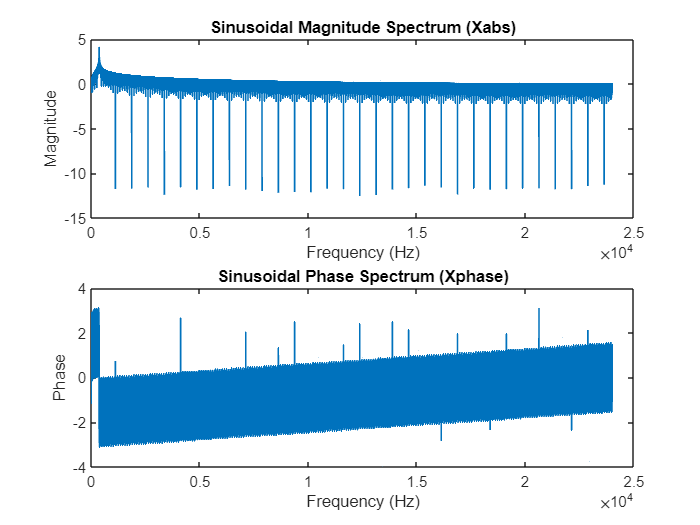

% ADD YOUR CODE

amplitude = 1.0;
sample_rate_hz = 48000; % In Hertz
frequency_hz = 375; % In Hertz
length_sec = 0.5; % Decimal Seconds
phase_radian = pi/2; % In Radians

[t_sin2, x_sin2] = generateSinusoidal(amplitude, sample_rate_hz, frequency_hz, length_sec, phase_radian); % Sinusoidal Function Called 

[f_sin2, Xabs_sin2, Xphase_sin2, Xre_sin2, Xim_sin2] = computeSpectrum(x_sin2, sample_rate_hz); % Spectrum of Sinusoidal Spectrum Function Called

figure("name", "Compare Subplots: Bonus");% Subplots for Sine Wave: Bonus
subplot(2,1,1);plot(f_sin2, log10(Xabs_sin2), "Linewidth",1);title("Sinusoidal Magnitude Spectrum (Xabs)");
xlabel("Frequency (Hz)");ylabel("Magnitude");
subplot(2,1,2);plot(f_sin2, Xphase_sin2, "Linewidth",1);title("Sinusoidal Phase Spectrum (Xphase)");
xlabel("Frequency (Hz)");ylabel("Phase");

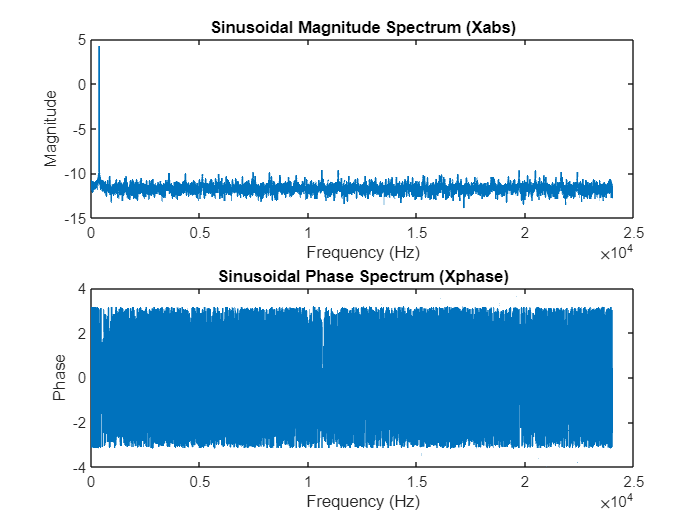

figure("name", "Compare Subplots: Bonus");% Subplots for Sine Wave: Bonus
subplot(2,1,1);plot(f_sin, log10(Xabs_sin), "Linewidth",1);title("Sinusoidal Magnitude Spectrum (Xabs)");
xlabel("Frequency (Hz)");ylabel("Magnitude");
subplot(2,1,2);plot(f_sin, Xphase_sin, "Linewidth",1);title("Sinusoidal Phase Spectrum (Xphase)");
xlabel("Frequency (Hz)");ylabel("Phase");

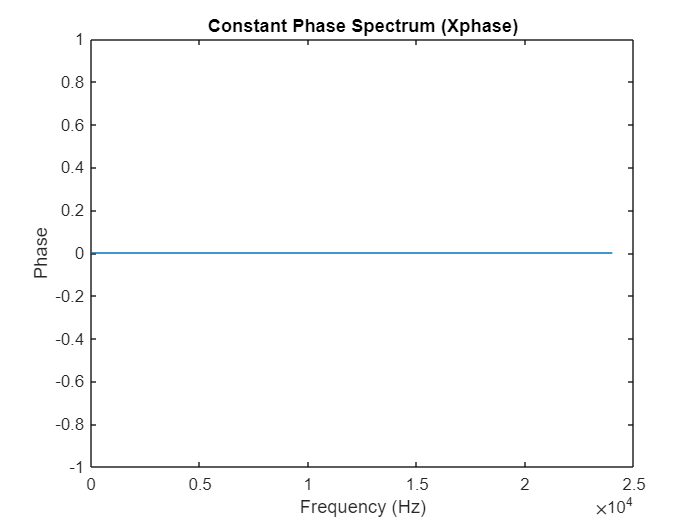

x_cons = zeros(length(x_sin), 1) + 1; % Constant Signal Called 

[f_cons, Xabs_cons, Xphase_cons, Xre_cons, Xim_cons] = computeSpectrum(x_cons, sample_rate_hz); % Spectrum of Sinusoidal Spectrum Function Called

figure("name", "Compare Subplots: Bonus");% Subplots for Sine Wave: Bonus
plot(f_cons, Xphase_cons, "Linewidth",1);title("Constant Phase Spectrum (Xphase)");
xlabel("Frequency (Hz)");ylabel("Phase");

% END OF YOUR CODE

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% AUTOGRADER -- DO NOT EDIT OR DELETE! %%%%%%%%
autograde('q3f', struct('bonusScore', 20), studentId);

q3f:	 1.00 / 5.00





%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

**Discussion: **This graph has a more noisy representation than Q3c. The two magnitude graphs do represent each other where there is one peak, but the phase graph of Q3f has a direction to the noise that is not seen in the Q3c graph where that noise is more evenly distributed. The discrepancy between the two plots may be due to the defined number of decimal places making the Q3f graph appear more noisy. Changing the length of the sine wave makes the Q3f graph similar to the Q3c graph.

The Fourier Transform for a constant signal should be a Dirac function. It doesn't exactly match the FFT plot because we use the length of the sinewave signal and the DFT will make it different.

## **Question 4. Spectrogram [30]**

### Q4(a) [10]

Write a function 

`[t, x_blk] = generateBlocks(x, sample_rate_hz, block_size, hop_size)` 

which blocks a given signal x according to the given parameters. The output t is a column vector containing the time stamps of the blocks (`N` by `1`) and `x_blk` is a matrix (`block_size` by `n_blocks`) where each column is a block of the signal. Note: You may need to zero-pad the input signal appropriately for the last block. Time stamps should be the time-stamp corresponding to the 1st sample of the block. 

**You are not allowed to use the MATLAB buffer method for this part.**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% AUTOGRADER -- DO NOT EDIT OR DELETE! %%%%%%%%
autograde('q4a', struct('adjustments', {[ ...
    {-1, 'wrong block numbers'}; ...
    {-1, 'wrong padding'}]}), studentId);

t
  - Correct shape.
  - Correct values.
x
  - Correct shape.
  - Correct values.
q4a:	 8.00 / 10.00

adjustments: 
	 -1.00 : wrong block numbers
	 -1.00 : wrong padding



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

### Q4(b) [10]

Write a function 

`[freq_vector, time_vector, magnitude_spectrogram] = mySpecgram(x, sample_rate_hz, block_size, hop_size, window_type)`

that computes the FFT per block windowed using the window type specified. 

- `freq_vector` is a column vector containing the frequency of the bins in Hz (`block_size/2+1` by `1`)

- `time_vector` is a column vector containing the time stamps of the blocks in seconds (`n_blocks` by `1`).

- `magnitude_spectrogram` is a `(block_size/2+1)`-by-`n_blocks` matrix where each column is the FFT of a signal block.  

- The parameter `window_type` is a string which can take the following values: `"rect`" for a rectangular window and `"hann"` for a Hann window. 

The function should also plot the magnitude spectrogram, labeling the time (in seconds) and frequency (in Hz) axes appropriately. You may assume that `block_size` is an even integer.

**Note:** You may use the MATLAB `fft`, `hann` and `image` methods. You can use the `generateBlocks` and `computeSpectrum` methods which you created earlier.

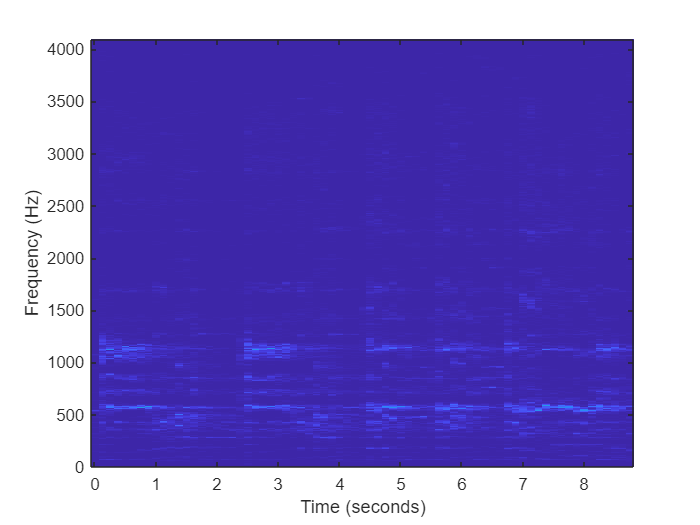

checking hann window
freq_vector
  - Correct shape.
  - Correct values.
time_vector
  - Correct shape.
  - Correct values.
magnitude_spectrogram
  - Correct shape.
  - Correct values.


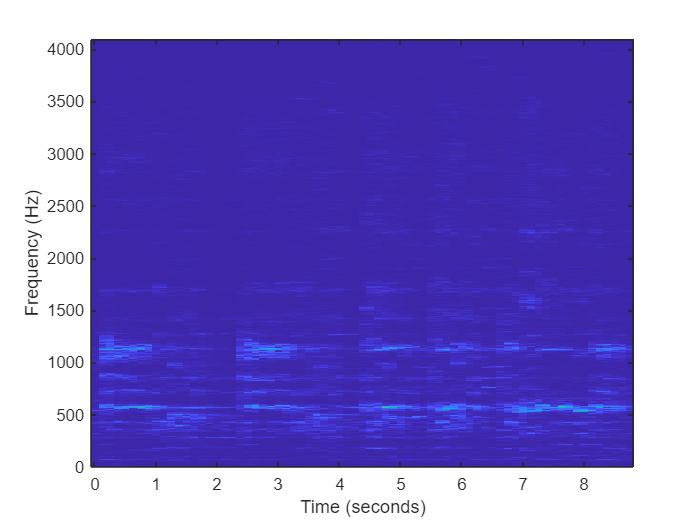

checking rect window
freq_vector
  - Correct shape.
  - Correct values.
time_vector
  - Correct shape.
  - Correct values.
magnitude_spectrogram
  - Correct shape.
  - Correct values.
q4b:	 5.50 / 10.00

adjustments: 
	 -2.50 : window must be applied in time-domain before computing fft.
	 -1.00 : y axis ticks are not actually in Hz
	 -1.00 : x axis ticks are not actually in seconds



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% AUTOGRADER -- DO NOT EDIT OR DELETE! %%%%%%%%
autograde('q4b', struct( ...
    'adjustments', {[ ...
    {-2.5, 'window must be applied in time-domain before computing fft.'}; ...
    {-1, 'y axis ticks are not actually in Hz'}; ...
    {-1, 'x axis ticks are not actually in seconds'}]}), studentId);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

### Q4(c) [7.5]

Now, add function calls to `mySpecgram()` in your main script to plot the magnitude spectrogram of the square wave generated in Question 2(b) using (1) the rectangular window, and (2) the hann window, with a separate plot for each. 

Take the block_size as 2048 and the hop_size as 1024. 

Discuss below the differences in the two spectrogram plots due to the different windows used. You may want to use the zoom feature on each plot to see the details more clearly. 

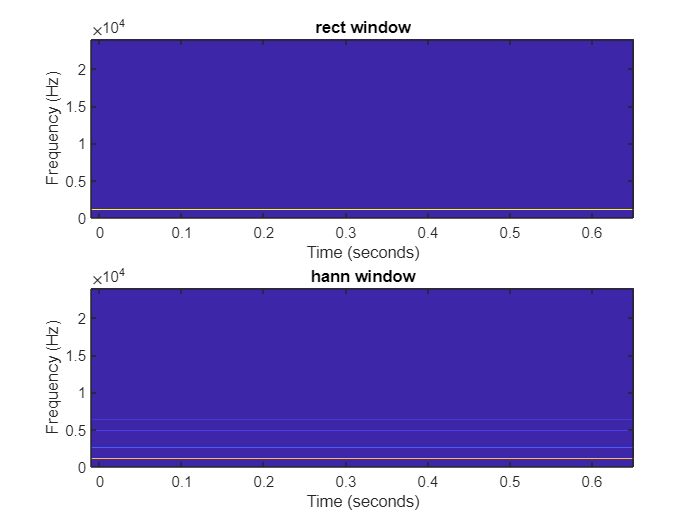

% ADD YOUR CODE

block_size = 2048;
hop_size = 1024;
subplot(2,1,1);
window_type = "rect";
[freq_vector_rect, time_vector_rect, magnitude_spectrogram_rect] = mySpecgram(x_sqr,sample_rate_hz,block_size,hop_size,window_type); % Function Called for Rect Window
title("rect window");
subplot(2,1,2);
window_type = "hann";
[freq_vector_hann, time_vector_hann, magnitude_spectrogram_hann] = mySpecgram(x_sqr,sample_rate_hz,block_size,hop_size,window_type); % Function Called for Hann Window
title("hann window")


% END OF YOUR CODE

**Discussion:** The rectangle window spectrogram has a frequency distribution with magnitudes that are much higher than the hann window spectrogram. This is noticeable from the brighter colors that are visible in the rectangle window spectrogram. The brighter frequency representation may be the results of side lobe leakage. The difference in the frequency spectrum representations may be due to the hann window reducing the side lobes for a better frequency resolution than the rectangle window. 

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% AUTOGRADER -- DO NOT EDIT OR DELETE! %%%%%%%%
autograde('q4c', struct('discussScore', 20), studentId);

q4c:	 3.50 / 7.50





%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

### Q4(d) [2.5]

Plot another spectrogram, using the hann window, for the same signal and the same block parameters using the MATLAB `spectrogram` method.

Note: `spectrogram` is a Signal Processing Toolbox command. Call `doc spectrogram` to get the documentation on its various options. Feel free to use the discussion board for this.

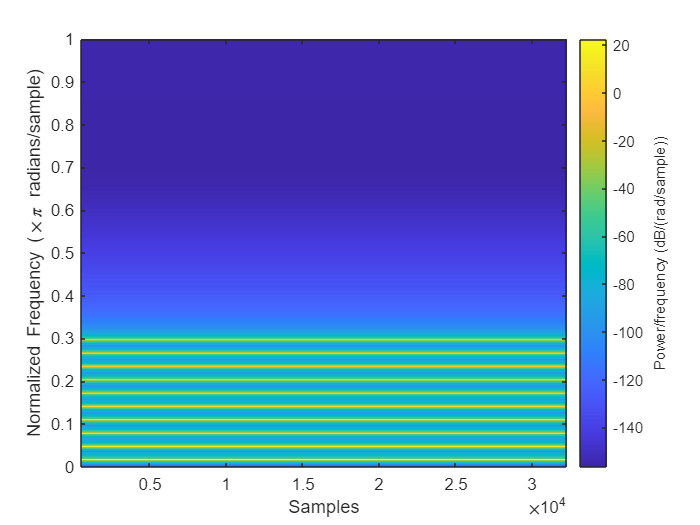

% ADD YOUR CODE

num_FFT_pts = block_size/2+1; % Calculated FFT points

figure;
spectrogram(x_sqr,hann(block_size),hop_size,num_FFT_pts,'yaxis') % MATLAB spectrogram method


% END OF YOUR CODE

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% AUTOGRADER -- DO NOT EDIT OR DELETE! %%%%%%%%
autograde('q4d', [], studentId);

q4d:	 2.50 / 2.50





%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## **Question 5. Sine-Sweep [Bonus for overachiever: 10]**

How would you approach generating a sine sweep in the spectral domain using only a single spectrum (i.e. a single complex-valued vector whose IFFT is a sine sweep). Write a script that generates a sine-sweep in the frequency domain using one single spectrum. You may not use the MATLAB chirp function.

You can call `sound(x, sample_rate_hz)` if you want to listen to your creation!

% ADD YOUR CODE

% END OF YOUR CODE

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% AUTOGRADER -- DO NOT EDIT OR DELETE! %%%%%%%%
autograde('q5', struct('bonusScore', 0), studentId);

q5:	 0.00 / 10.00





%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

autograde('summary', [], studentId);

Question         Score        Comment
--------     -------------    -------
q0             5.00/  5.00    
q1a           10.00/ 10.00    
q1b            2.50/  2.50    
q1c            2.50/  2.50    
q2a           15.00/ 15.00    
q2b            2.50/  2.50    
q2c            2.50/  2.50    
q3a           14.25/ 15.00    
q3b            0.95/  1.00    
q3c            6.00/  8.00    -2.00 : filtering by max power does not make sense for non-pure signal like square wave.
q3d            0.00/  2.00    
q3e            1.00/  4.00    
q3f*           1.00/  0.00    
q4a            8.00/ 10.00    -1.00 : wrong block numbers;  -1.00 : wrong padding
q4b            5.50/ 10.00    -2.50 : window must be applied in time-domain before computing fft.;  -1.00 : y axis ticks are not actually in Hz;  -1.00 : x axis ticks are not actually in seconds
q4c            3.50/  7.50    
q4d            2.50/  2.50    
q5*            0.00/  0.00    
--------     -------------    -------
Standard      81.70/100.0